# ความน่าจะเป็นและสัญญาณสุ่ม (Probability & Random Signal)

# ตอนที่ 2 : ตัวแปรสุ่ม (1/2) (Random Variable)

จะอย่างไรก็ตามการอธิบายความไม่แน่นอนในลักษณะบวกลบนี้มีข้อเสียในเรื่องของการหาแนวโน้มและความสัมพันธ์เนื่องจาก**การระบุความไม่แน่นอนแบบบวกลบไม่ได้ให้ข้อมูลการแจกแจงของค่ามาแต่อย่างใด** ถึงแม้ค่าจะมีช่วงที่กำหนดมา แต่ค่าเฉลี่ยจริงๆนั้นอาจะไม่ได้อยู่ที่กึ่งกลางของช่วงก็เป็นได้ อีกทั้งความแปรปรวนของค่าอาจะมีมากหรือน้อยที่แตกต่างกันก็เป็นได้ ดังนั้น ในหลายครั้ง เราจะใช้ความน่าจะเป็น (probability) ในการอธิบายค่าที่เป็นไปได้ของตัวแปร

**ตัวแปรที่มีความไม่แน่นอนจะถูกเรียกว่า ตัวแปรสุ่ม (random variable)**ซึ่ง เราสามารถอธิบายค่าที่เป็นไปได้ของตัวแปรสุ่มนี้ผ่านความน่าจะเป็น (probability) ซึ่งตัวแปรนี้สามารถมีค่าเป็นได้ 2 ประเภทหลัก

## ตัวแปรสุ่มแบบไม่ต่อเนื่อง (discrete random variable)

ประเภทแรกคือ**ตัวแปรสุ่มแบบไม่ต่อเนื่อง (discrete random variable) ซึ่งป็นตัวแปรที่มีค่าที่เป็นไปได้อยู่ในเซ็ตที่นับได้** ยกตัวอย่างการโยนเหรียญหัวก้อย หากเรากำหนดให้ $X$เป็นตัวแปรสุ่มที่บ่งบอกว่าเหรียญเป็นหัวหรือเป็นก้อย โดยกำหนดให้ เมื่อ $X=1$ เป็นเหตุการณ์ที่เหรียญออกเป็นหัว ส่วน$X=0$ เป็นเหตุการณ์ที่เหรียญออกเป็นก้อย เราจะสามารถเขียนความน่าจะเป็น $\mathrm{P}\left(\cdot \right)$ ได้ดังต่อไปนี้


$$\begin{array}{l}
\mathrm{P}\left(X=1\right)=0\ldotp 5\\
\mathrm{P}\left(X=0\right)=0\ldotp 5
\end{array}$$


สมการการทั้งสองอธิบายถึงความน่าจะเป็นที่เหรียญจะออกหัวหรือก้อยนั้นเป็น 0.5 ทั้งคู่ (50%)

**ความน่าจะเป็นนั้นจะเอาไว้ใช้อธิบายเหตุการณ์ (event) เสมอ** ในการอธิบายอย่างเป็นทางการ **เราจำเป็นต้องแปลงความหมายของเหตุการณ์ให้อยู่ในรูปของสมการหรืออสมการ** ยกตัวอย่างเช่นการทอยลูกเต๋าหกด้าน หากต้องการหาคความน่าจะเป็นที่ลูกเต๋าออกด้านที่มีค่าน้อยกว่า 4 เราต้องกำหนดให้ $X$ เป็นค่าของด้านลูกเต๋าที่ออก และเหตุการณ์ที่ลูกเต๋าออกด้านที่มีค่าน้อยกว่า 4 จะสามารถถูกเขียนเป็นอสมการได้คือ $X<4$ ดังนั้น ความน่าจะเป็นสามารถเขียนได้เป็นสมการต่อไปนี้


$$\mathrm{P}\left(X<4\right)=0\ldotp 5$$


**เราจะไม่เขียนว่า **$\mathrm{P}\left(X\right)$** เนื่องจาก **$X$** ไม่ใช่เหตุการณ์**

## ตัวอย่างที่ 1 : การทอยลูกเต๋า

กำหนดให้ลูกเต๋าหกด้านมีความน่าจะเป็นที่เท่าๆกันที่จะออกด้านใดด้านหนึ่ง ดังนั้น เราสามารถเขียนความสัมพันธ์ของความน่าจะเป็นได้ดังต่อไปนี้


$$\mathrm{P}\left(X=x\right)=\frac{1}{6}\;\;\;\;\;\textrm{โดยที่}\;x\in \left\lbrace 1,2,3,4,5,6\right\rbrace$$


เราสามารถกราฟความสัมพันธ์ระหว่างค่าของ $X$ และความน่าจะเป็นได้ดังต่อไปนี้

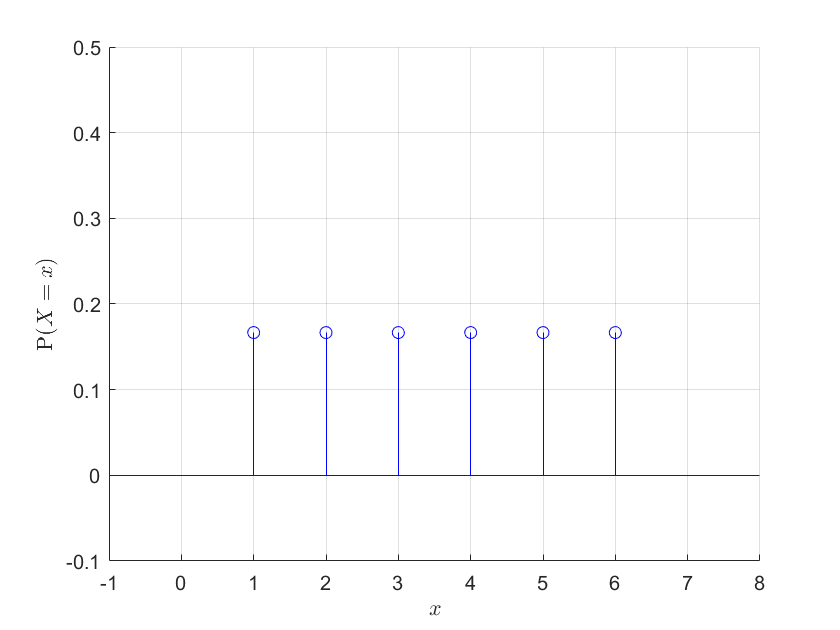

clf;
ax = axes;
grid(ax,'on')
hold(ax,'on')
x = 1:6;
stem(ax,x,(1/6)*ones(size(x)),'b')
axis(ax,[-1 8 -0.1 0.5])
xlabel('$x$','Interpreter',"latex")
ylabel('$\mathrm{P}(X=x)$','Interpreter',"latex")

**การแจกแจงที่ความน่าจะเป็นของทุกเหตุการณ์เท่ากันถูกเรียกว่า การแจกแจงแบบยูนิฟอร์ม (uniform distribution) ซึ่งเราสามารถเขียนเป็นโปรแกรมสุ่มโดยใช้ฟังก์ชัน randi ได้ดังต่อไปนี้**

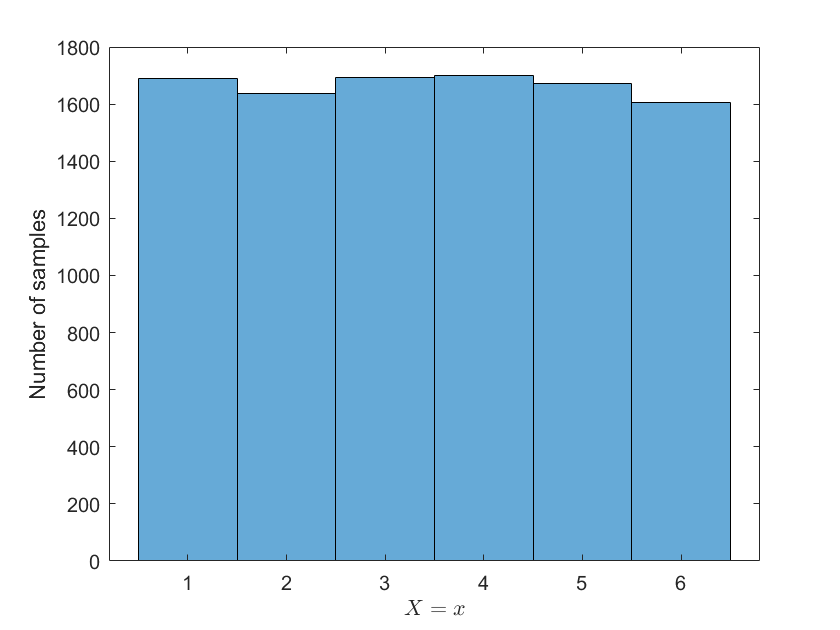

imax = 6;
imin = 1;
sz = [1 10000]; % one row 100 columns
X = randi(imax-imin+1,sz)+imin-1;
clf
ax = axes;
histogram(ax,X)
xlabel('$X=x$','Interpreter',"latex")
ylabel('Number of samples')

หากโจทย์เปลี่ยนเป็นการทอยลูกเต๋า 2 อันและนับผลรวมจากแต้มของหน้าลูกเต๋าทั้งสอง เราจะได้ความน่าจะเป็นของแต่ละผลรวมดังต่อไปนี้


$$\begin{array}{l}
\mathrm{P}\left(X=2\right)=\mathrm{P}\left(X=12\right)=\frac{1}{36}\\
\mathrm{P}\left(X=3\right)=\mathrm{P}\left(X=11\right)=\frac{2}{36}\\
\mathrm{P}\left(X=4\right)=\mathrm{P}\left(X=10\right)=\frac{3}{36}\\
\mathrm{P}\left(X=5\right)=\mathrm{P}\left(X=9\right)=\frac{4}{36}\\
\mathrm{P}\left(X=6\right)=\mathrm{P}\left(X=8\right)=\frac{5}{36}\\
\mathrm{P}\left(X=7\right)=\frac{6}{36}
\end{array}$$


โดยที่ $X$ คือผลรวมของหน้าลูกเต๋าที่ออก ซึ่งสามารถกราฟความสัมพันธ์ได้ดังต่อไปนี้

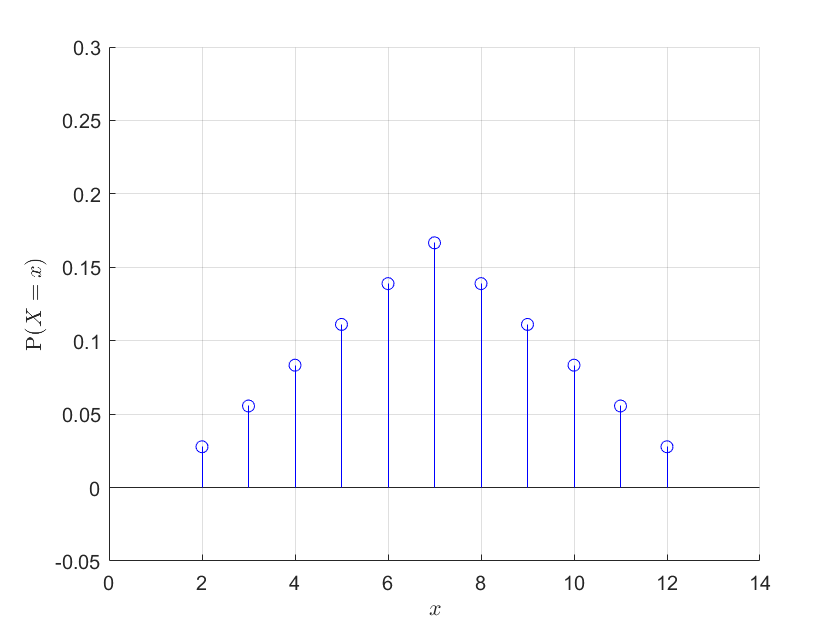

clf;
ax = axes;
grid(ax,'on')
hold(ax,'on')
x = 2:12;
stem(ax,x,(6-abs(x-7))/36,'b')
axis(ax,[0 14 -0.05 0.3])
xlabel('$x$','Interpreter',"latex")
ylabel('$\mathrm{P}(X=x)$','Interpreter',"latex")

ในบ่อยครั้ง เหตุการณ์อาจะมีจำนวนมากซึ่งการเขียนสมการเป็นทีละเหตุการณ์อาจไม่ใช่วิธีที่สะดวกที่สุด เราสามารถใช้ฟังก์ชันในการอธิบายการแจกแจงของความน่าจะเป็น หรือ ฟังก์ชันการแจกแจงความน่าจะเป็น $f_X \left(\cdot \right)$ (probability density function/ pdf)  สำหรับตัวอย่างการทอยลูกเต๋าสองอัน เราสามารถเขียนฟังก์ชันการแจกแจงความน่าจะเป็นได้ดังต่อไปนี้


$$f_X \left(x\right)=\left(x-1\right)\cdot \theta \left(x-2\right)-2\left(x-7\right)\cdot \theta \left(x-7\right)+\left(x-13\right)\cdot \theta \left(x-13\right)$$


โดยที่ $x$ คือค่าของผลรวมหน้าลูกเต๋า (จำนวนเต็ม)

ไม่ว่าความน่าจะเป็นจะมีการแจกแจงอย่างไร เราสามารถเขียนความน่าจะเป็นของแต่ละจำนวนเต็มให้อยู่ในรูปของเวกเตอร์ที่มีจำนวนจำกัดได้ โดยการกำหนดตัวแปรที่มีจำนวนจำกัดและใช้ผ่านฟังก์ชันเช่น


$$f_X \left(x\right)=\frac{6-\left|x-7\right|}{36}\;\mathrm{โดยที่}\;x\in \left\lbrace 2,3,\cdots ,12\right\rbrace$$


**ถ้าหากเราเขียนความน่าจะเป็นในรูปแบบที่จำกัดได้ เราก็สามารถเขียนโปรแกรมในการสุ่มตามการแจกแจงใดๆได้ ซึ่งเราจะใช้ฟังก์ชัน randsample (จำเป็นต้องใช้ Statistics & Machine Learning Toolbox) ได้ดังต่อไปนี้**

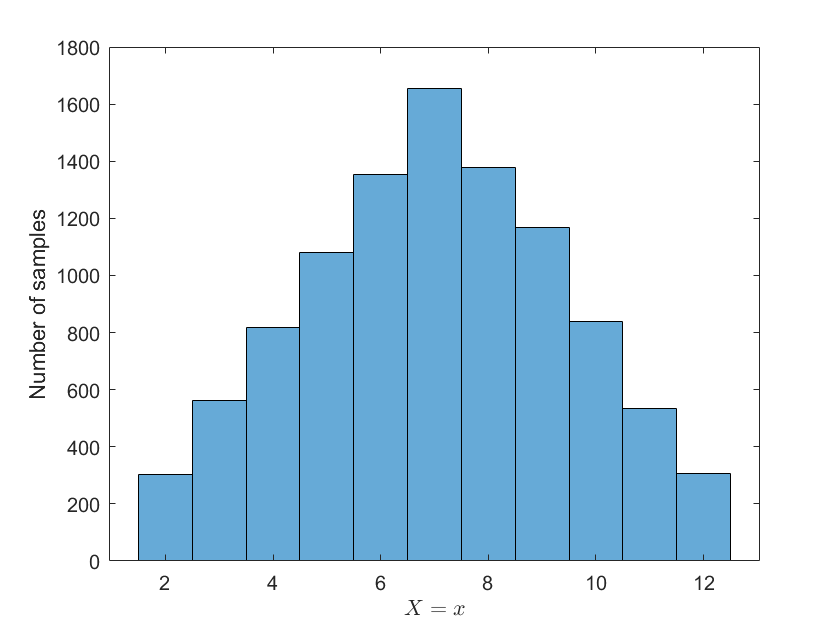

x = 2:12;
pdf = (6-abs(x-7))/36;
sz = 10000;
X = randsample(x,sz,true,pdf);

clf
ax = axes;
histogram(ax,X)
xlabel('$X=x$','Interpreter',"latex")
ylabel('Number of samples')

หนึ่งในคุณสมบัติของฟังก์ชันการแจกแจงความน่าจะเป็นสำหรับตัวแปรที่ไม่ต่อเนื่องคือผลรวมของความน่าจะเป็นของทุกเหตุการณ์ต้องเท่ากับ 1  หรือเขียนเป็นสมการได้ดังต่อไปนี้


$$\sum_x f_X \left(x\right)=1$$
 

อีกหนึ่งในคุณสมบัติของฟังก์ชันการแจกแจงคือฟังก์ชันต้องไม่เป็นลบ


$$0\le f_X \left(x\right)\le 1$$
